function [X, Y] = nodes(a, b, n, f)
X = linspace(a, b, n);
Y = f(X);
end

function res = export_nodes(filename, X, Y)
file = fopen(filename, "w");
fwrite(file, numel(X), "int");
fwrite(file, X, "double");
fwrite(file, Y, "double");
fclose(file);
end

f = @(x) tan(x) + cos(x) + 0.1;

a = -0.5;
b = 0.5;

fX = linspace(a, b, 1000);
fY = f(fX);

f(0.4)

ans = 1.4439

[X_test, Y_test] = nodes(a, b, 4, f)

X_test =    -0.5000   -0.1667    0.1667    0.5000


Y_test =     0.4313    0.9179    1.2544    1.5239


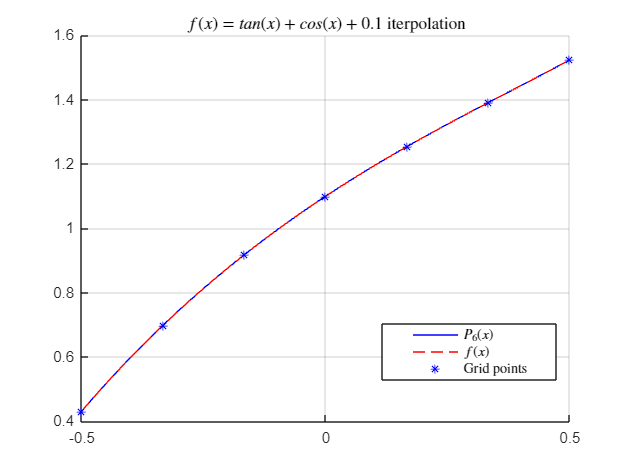


[X, Y] = nodes(a, b, 7, f);

export_nodes("poly7_SRC.bin", X, Y);

T1 = readtable("poly7_RES.csv");
figure
hold on
plot(T1{1:end, 1}, T1{1:end, 2}, "b-")
plot(fX, fY, "r--")
plot(X, Y, "b*")
grid on
title("$f(x) = tan(x) + cos(x) + 0.1$ iterpolation", Interpreter="latex")
legend("$P_6(x)$", "$f(x)$", "Grid points", Interpreter="latex", Position=[0.6073 0.1990 0.2762, 0.1172])

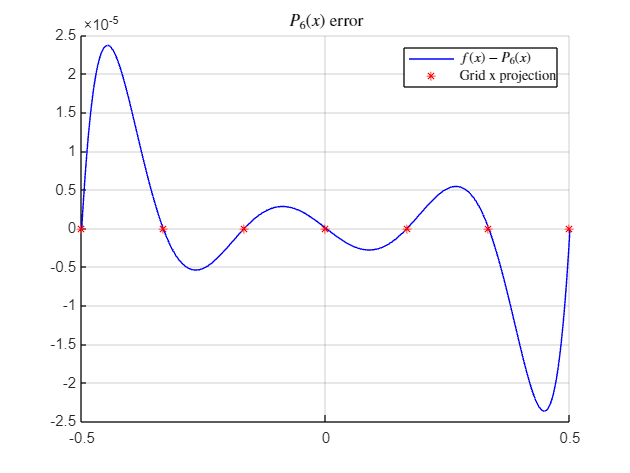

figure
hold on;
dY = f(T1{1:end, 1}) - T1{1:end, 2};
plot(T1{1:end, 1}, dY, "b");
plot(X, zeros(numel(X), 1), "r*");
grid on;
title("$P_6(x)$ error", Interpreter="latex");
legend("$f(x) - P_6(x)$", "Grid x projection", Interpreter="latex")

syms t

f_sym = diff(tan(t) + cos(t) + 0.5, 3);
Mn = zeros(70, 1);

Xt = linspace(a, b, 50);

for i = 2:70
    for j = 1:numel(Xt)
        Mn(i) = max(Mn(i), abs(double(subs(f_sym, t, Xt(j)))));
    end

    Mn(i) = max(Mn(i), abs(double(subs(f_sym, t, a))));
    Mn(i) = max(Mn(i), abs(double(subs(f_sym, t, b))));

    f_sym = diff(f_sym);
end

Mn

Mn = 1.0e+99 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


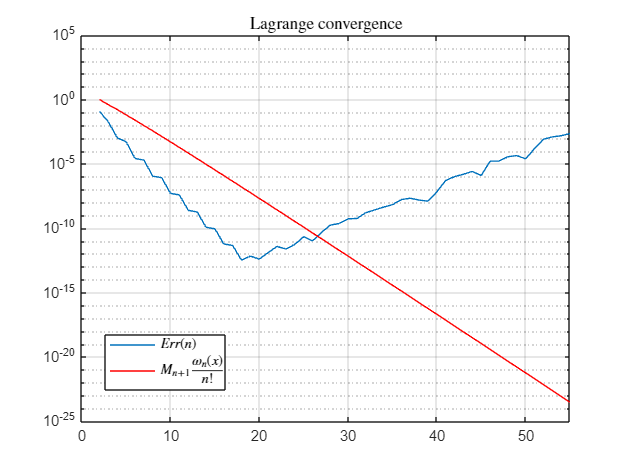


figure
for i = 2:70
    [X2, Y2] = nodes(a, b, i, f);
    export_nodes(sprintf("./data/rpoly%i_SRC.bin", i), X2, Y2);
end

T2 = readtable("rpoly_RES.csv");

for i = 2:70
    [X2, Y2] = nodes(a, b, i, f);
    
    wx = 1;
    for j = 1:numel(X2)
        wx = wx * (T2{i, 1} - X2(j));
    end

    Mn(i) = double(Mn(i) * abs(wx) / gamma(i));
end

semilogy(2:100, T2{1:end, 2});
hold on
semilogy(2:70, Mn(2:70), "r-");
grid on

xlim([0.0 55.0])
legend(["$Err(n)$", "$M_{n+1}\frac{\omega{}_n(x)}{n!}$"], "Interpreter", "latex", "Position", [0.1674 0.1779 0.1913, 0.1147])
title("Lagrange convergence", Interpreter="latex")